# WP4

Nota: prima di eseguire il codice assicurarsi di aver impostato come working directory di MATLAB la cartella "WP4".

clear all;  clc;

## Progettazione di un controllore feedback linearization di tipo Input/Output

Il controllore basato su feedback linearization è stato realizzato con la tecnica Input/Output feedback linearization poiché l'obiettivo è quello di inseguire un riferimento (costante o tempo variante).

Dapprima, si trova l'ingresso di controllo linearizzante per il sistema derivando due volte  (il grado relativo del sistema è r=2 e quindi non ci sono dinamiche nascoste): 


$$ u(t) = \frac{1}{p_3x_1}\left[(p_1+x_2)^2x_1-(p_1+x_2)p_1g_e+p_2x_1x_2+p_3i_ex_1-v(t) \right]$$


Tale ingresso impone che $x_1 \not= 0\ldotp$ Applicando l'ingresso linearizzante al sistema, si ottiene il seguente sistema equivalente: $\ddot{y} = v(t)$. Per determinare l'ingresso equivalente $v\left(t\right)$ è stato fatto utilizzando il metodo "analitico", ovvero la progettazione diretta nel dominio del tempo. Si è scelto come ingresso di controllo equivalente $v(t) = \ddot{y}_d + \alpha(\dot{y}-\dot y_d)+\beta(y-y_d)$, dove $\alpha, \ \beta \in \mathbb{R}$, per cui si ricava facilmente che: $( \ddot{y} - \ddot{y}_d) - \alpha(\dot{y}-\dot {y}_d)-\beta(y-y_d) = 0$. Grazie a questa scelta, è possibile inseguire sia riferimenti costanti che riferimenti tempo varianti. Si osservi che nel caso particolare di riferimento costante le derivate di $y_d$ possono essere trascurate.

L'equazione ottenuta è un equazione differenziale lineare omogenea del secondo ordine a coefficienti costanti e il polinomio caretteristico associato è $\lambda^2 -\alpha\lambda-\beta = 0$. Per ottenere asintotica stabilità è necessario che non ci siano variazioni di segno nei coefficienti del polinomio caratteristico, dunque dev'essere $\alpha <0 \ e  \ \beta<0 $. Per questo motivo si ricerceranno dei parametri $\alpha$ e $\beta$ che soddisfanno tale vincolo.

syms alpha beta
assume(alpha<0)
assume(beta<0)

A questo punto, si scelgono i parametri $\alpha$ e $\beta$ imponendo le prestazioni dinamiche desiderate tramite la tecnica del pole placement. In particolare si scelgono un tempo di assestamento pari a $t_s =6\min$ e $\zeta =1$e si trovano i valori di $\alpha$ e $\beta$ corrispondenti.

charpoly = [1 -alpha -beta];
ts = 6;
zita = 1;
num = interp1([0.5 1/sqrt(2) 1], [8.0 5.9 5.8],zita);
omega_n = num/ts;
des_poly = [1 2*zita*omega_n omega_n^2];
sol = solve(charpoly == des_poly, [alpha, beta]);
alpha = double(sol.alpha), beta = double(sol.beta)

alpha = -1.9333

beta = -0.9344

A questo punto realizziamo una simulazione del sistema a ciclo chiuso e ne valutiamo le performance rispetto al task di regolazione con $r\left(t\right)=0\ldotp 0451\;g/l$

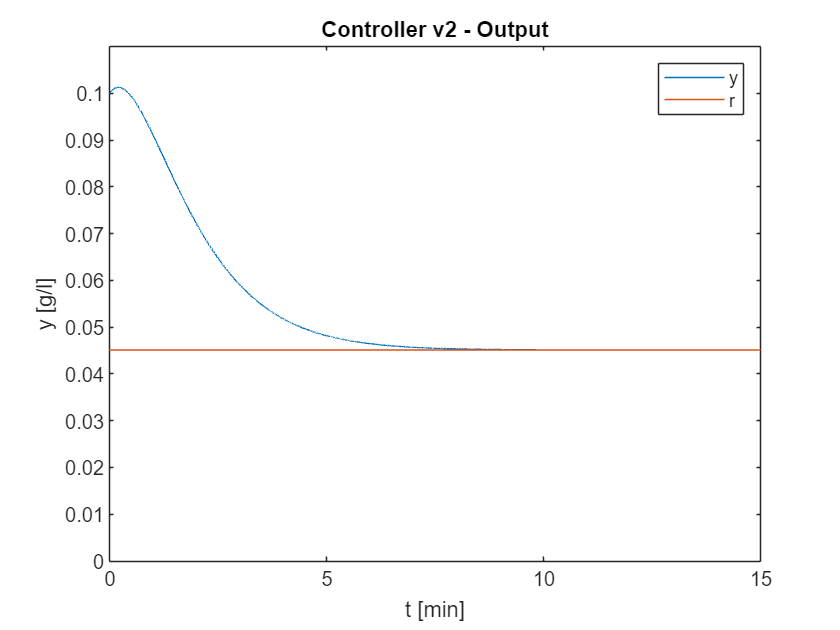

simout = sim('v2_sim.slx');
y = simout.y;
t = simout.t.Time;
u = simout.u;
figure;
plot(t, y)
xlim([0,15])
title('Controller v2 - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

y_stepinfo = stepinfo(y,t,y(end))

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 6.2411
     SettlingTime: 6.5063
      SettlingMin: 0.0451
      SettlingMax: 0.1013
        Overshoot: 124.5307
       Undershoot: 0
             Peak: 0.1013
         PeakTime: 0.2053


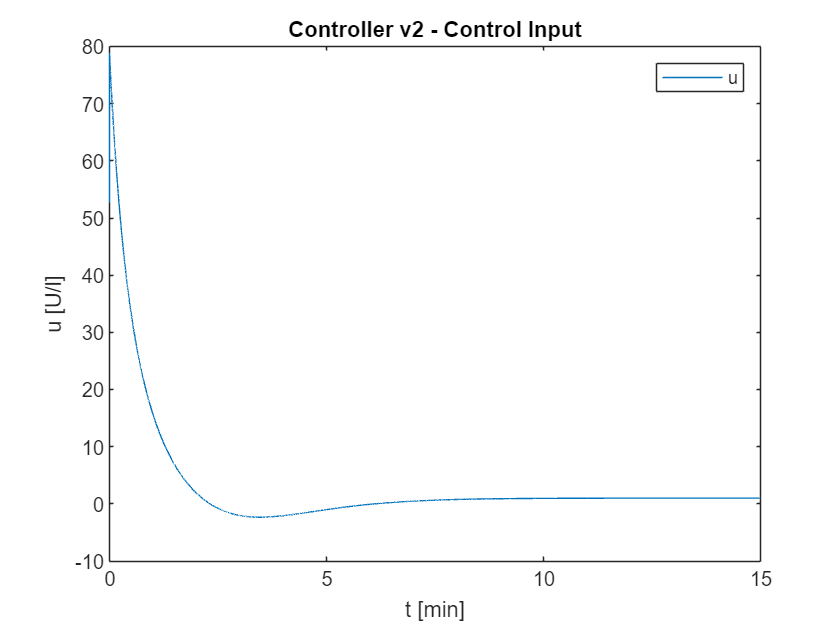

figure;
plot(t, u)
xlim([0,15])
title('Controller v2 - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 5.4424
     SettlingTime: 11.0099
      SettlingMin: -2.3374
      SettlingMax: 78.8699
        Overshoot: 7.7694e+03
       Undershoot: 233.2180
             Peak: 78.8699
         PeakTime: 1.9110e-10


u_max = max(u), u_min = min(u)

u_max = 78.8699

u_min = -2.3374

Il controllore realizzato ha delle buone performance se confrontato coi controllori realizzati nel WP2, tuttavia questo non è in grado di reiettare eventuali disturbi a gradino, poiché non è presente l'azione integrale.

Per ulteriori simulazioni con riferimenti tempo varianti fare riferimento al seguente file Simulink:

open_system('v2_sim.slx')

## Progettazione di un controllore feedback linearization con azione integrale

clear all, clc;

Si vuole realizzare un controllore sfruttando la stessa tecnica di controllo precedentemente usata, ma questa volta si vuole fare in modo di reiettare eventuali disturbi a gradino. A questo scopo si introduce l'azione integrale. Estendiamo lo stato del sistema linearizzato per aggiungere l'azione integrale.

Una volta che applichiamo l'ingresso equivalente al sistema questo diventa: $\ddot{y} = v(t)$. Questo sistema può essere scritto come segue:


$$\begin{cases}
\dot{x}_1 = x_2  \\
\dot{x}_2 = v \\
\dot{z} = y_d-y \\
y = x_1
\end{cases}

\qquad \Rightarrow \qquad
\begin{cases}
\dot{x}_1 = x_2  \\
\dot{x}_2 = \ddot{y}_d + \alpha(x_2-\dot{y}_d) + \beta(x_1-y_d) + \gamma z \\
\dot{z} = y_d-x_1 \\
y = x_1
\end{cases}
$$


che, riscritto in forma matriciale, diventa:


$$\left[\matrix{\dot{x}_1 \cr \dot{x}_2 \cr \dot{z}}\right]

=
\left[\matrix{0 & 1 & 0 \cr \beta & \alpha & \gamma \cr -1 &0 &0}\right]
\left[\matrix{x_1 \cr x_2 \cr z}\right]
+
\left[\matrix{0 & 0 & 0 \cr -\beta & -\alpha & 1 \cr 1 &0 &0}\right]
\left[\matrix{y_d \cr \dot{y}_d\cr \ddot{y}_d}\right]

$$


La matrice dinamica a ciclo chiuso del sistema retroazionato è:

syms alpha beta gamma
assume(alpha<0)
assume(beta<0)
assume(gamma>0)
A = [0 1 0; beta alpha gamma; -1 0 0];
char_poly_coeff = charpoly(A)

$$char\_poly\_coeff = \left(\begin{array}{cccc} 1 & -\alpha & -\beta & \gamma \end{array}\right)$$

A questo punto cerchiamo di imporre il comportamento desiderato al sistema. Siccome il polinomio caratteristico è del terzo ordine, lo si scompone nel prodotto fra un monomio e un polinomio del secondo ordine. Dopodiché per imporre la dinamica desiderata, si sfrutta l'euristica per la quale se il terzo polo è ad alta frequenza, il comportamento del sistema è approssimativamente uguale al sistema del secondo ordine, il quale viene opportunamente scelto scegliendo $t_s =15\min$ e $\zeta =0\ldotp 9$.

syms s zita w_n p
desired_poly = (s^2 + 2*zita*w_n*s + w_n^2)*(s-p);
desired_poly_coeff = fliplr(coeffs(desired_poly, s));

sol = solve(char_poly_coeff==desired_poly_coeff,[alpha, beta, gamma],"ReturnConditions",true);

ts = 15;
zita = 0.90;
num = interp1([0.5 1/sqrt(2) 1], [8.0 5.9 5.8],zita);
omega_n = num/ts;
sol_2 = solve(s^2+2*zita*omega_n*s+omega_n^2==0, [s]);
minimum_pole = min(real(eval(sol_2)));
p = minimum_pole * 10; %Scegliamo p con una frequenza di 10 volte maggiore rispetto al polo dominante
alpha = double(subs(sol.alpha,{'zita','w_n','p'}, [zita, omega_n, p]));
beta = double(subs(sol.beta,{'zita','w_n','p'}, [zita, omega_n, p]));
gamma = double(subs(sol.gamma,{'zita','w_n','p'}, [zita, omega_n, p]));


A questo punto realizziamo una simulazione del sistema a ciclo chiuso e ne valutiamo le performance rispetto al task di regolazione con $r\left(t\right)=0\ldotp 0451\;g/l$

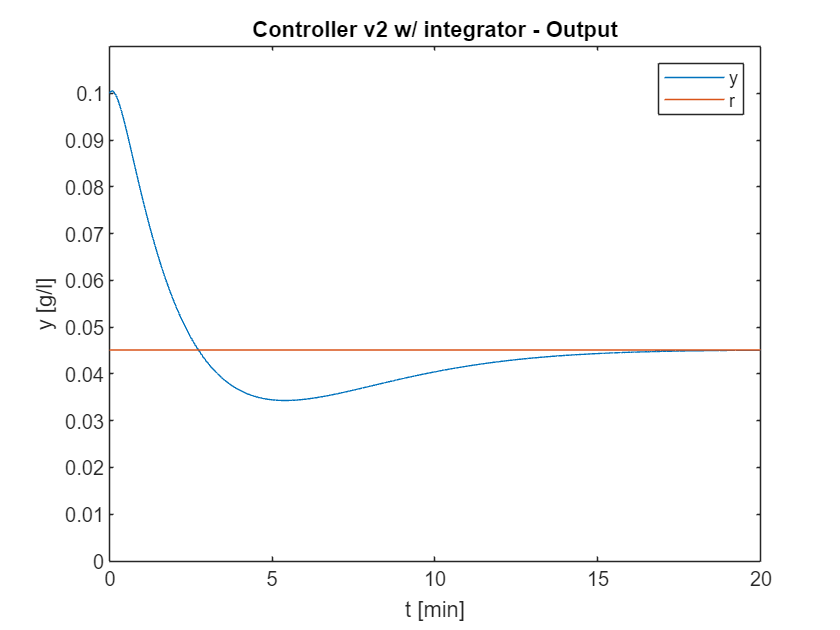

enable_disturbances = 0;
simout = sim('v2_sim_integral_action.slx');
y = simout.y;
t = simout.t.Time;
u = simout.u;
% Output
figure;
plot(t, y)
xlim([0,20])
title('Controller v2 w/ integrator - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

y_stepinfo = stepinfo(y,t,y(end)), undershoot=abs(min(y)-0.045102)/0.045102

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 14.0847
     SettlingTime: 14.5727
      SettlingMin: 0.0343
      SettlingMax: 0.1005
        Overshoot: 122.7920
       Undershoot: 0
             Peak: 0.1005
         PeakTime: 0.0768


undershoot = 0.2391

Osserviamo che l'approssimazione del polo dominante ha permesso di imporre il tempo di assestamento desiderato di 15 min. In questo caso la sottoelongazione percentuale è di circa il 23% e tale risultato rende le performance di questo controllore peggiori rispetto a quelle dei controllori proposti nel WP2.

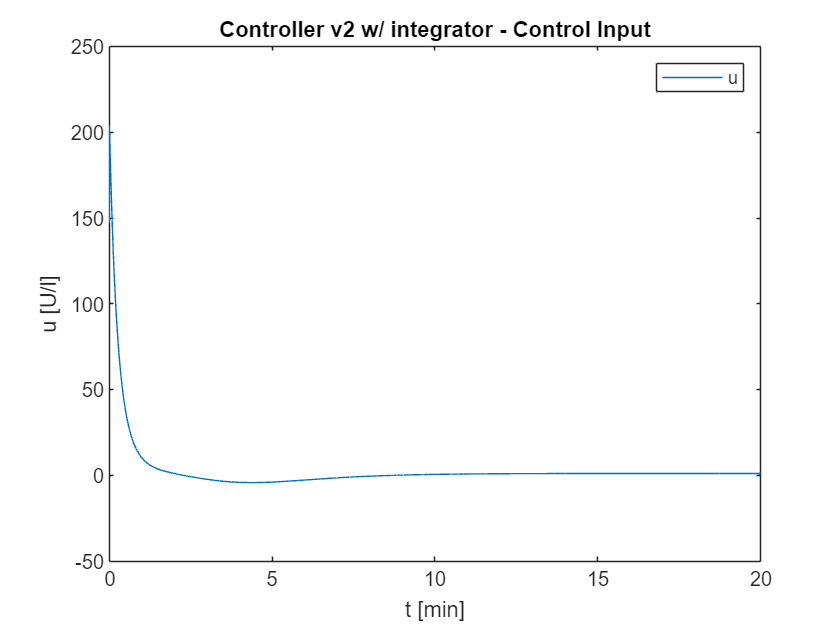

figure;
plot(t, u)
xlim([0,20])
title('Controller v2 w/ integrator - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end))

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 5.7979
     SettlingTime: 20.0000
      SettlingMin: -4.2845
      SettlingMax: 203.9538
        Overshoot: 2.0250e+04
       Undershoot: 427.4994
             Peak: 203.9538
         PeakTime: 2.4802e-10


u_max = max(u), u_min = min(u)

u_max = 203.9538

u_min = -4.2845

Le prestazioni non sono molto soddisfacenti soprattutto in termini dell'azione di controllo, la quale ha picchi positivi e negativi molto elevati. In particolare, a causa del picco negativo di -50 U/l il controllore sarà particolarmente affetto dagli effetti di saturazione.

La taratura di questo controllore risulta ostica per via delle forti sottoelongazioni e dello sforzo di controllo introdotti dall'azione integrale. Ciononostante questo controllore è in grado di assorbire disturbi a gradino sull'ingresso. 

Per ulteriori simulazioni con riferimenti tempo varianti fare riferimento al seguente file Simulink:

open_system('v2_sim_integral_action.slx')

#### Simulazione con disturbo additivo a gradino

Il sistema è stato simulato con disturbo additivo a gradino che agisce al tempo $t=20\min$ con un ampiezza di -50U/l. Il gradino ad ampiezza negativa permette di simulare un picco glicemico nel paziente (o più in generale un'incertezza sul modello).

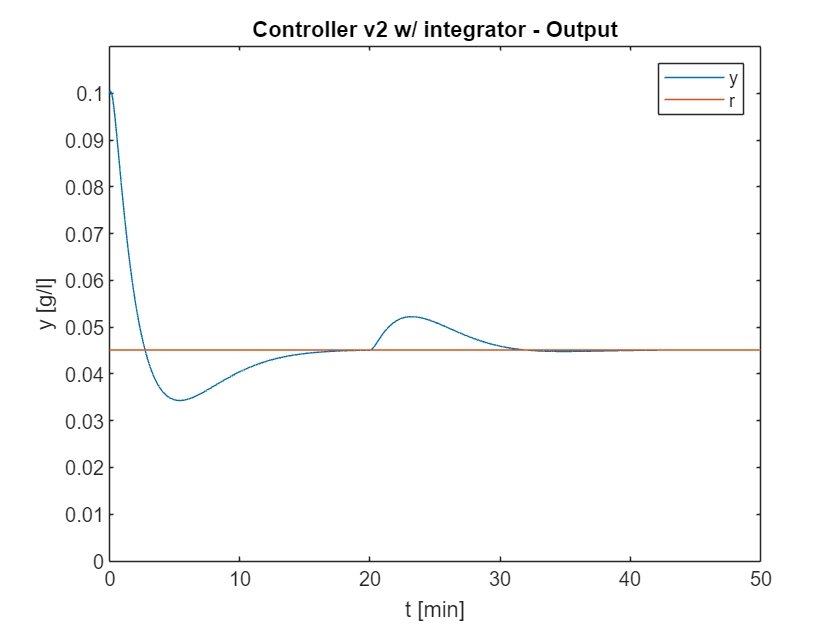

enable_disturbances = 1;
simout = sim('v2_sim_integral_action.slx');
y = simout.y;
t = simout.t.Time;
u = simout.u;
% Output
figure;
plot(t, y)
xlim([0,50])
title('Controller v2 w/ integrator - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

Osserviamo come il controllore riesca ad assorbire il disturbo che agisce al tempo $t=20\min$ in circa 12 minuti.

## Feedback linearization + PID

Per provare ad introdurre diversamente l'azione integrale si è provato ad utilizzare come ingresso di controllo equivalente un controllore PID. Per fare ciò si vede il sistema linearizzato come un doppio integratore $\frac{1}{s^2 }$ (assumendo che la linearizzazione sia perfetta) e si progetta il PID su tale sistema equivalente.

% La funzione di trasferimento del sistema da controllare è:
s = tf('s');
P = 1/s^2;

Per fare il tuning del controllore, si è utilizzata la tecnica del luogo delle radici. A questo scopo si è sfruttato il tool Control System Designer il quale ha facilitato la procedura di sintesi del controllore. La sessione di lavoro è stata registrata nel file 'ControlSystemDesignerSession.mat' e può essere aperta dal tool.

rltool(P,1);

La procudura di sintesi ha prodotto il seguente risultato (il controllore 3 nella sesssione salvata):

C = 4.2975*(s+0.191)*(s+0.1311)/(s*(s+3.039));

A questo punto il PID è stato implementato su Simulink. Simuliamone il comportamento per valutare le performance rispetto al task di regolazione con $r\left(t\right)=0\ldotp 0451\;g/l$

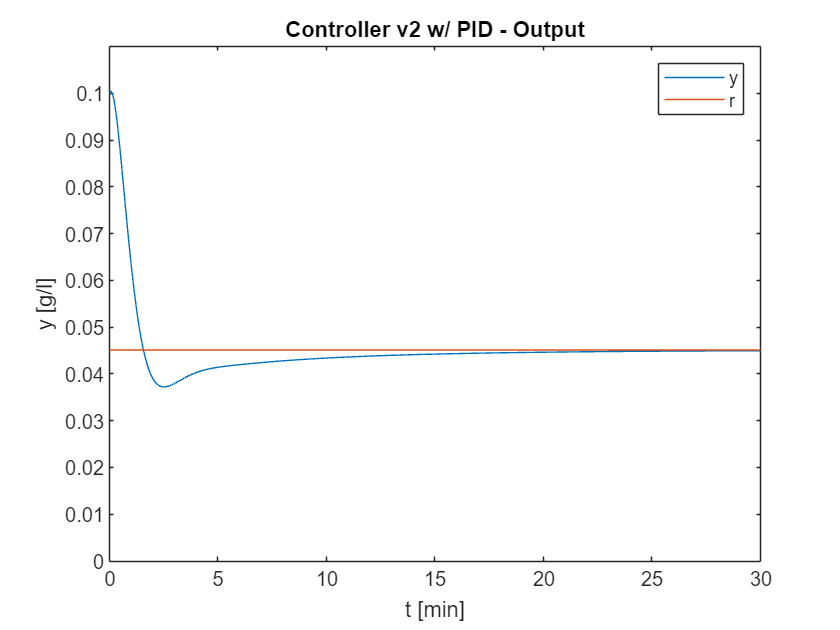

simout = sim('v2_sim_PID.slx');
y = simout.y;
t = simout.t.Time;
u = simout.u;
figure;
plot(t, y)
xlim([0,30])
title('Controller v2 w/ PID - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

y_stepinfo = stepinfo(y,t,y(end)), undershoot=abs(min(y)-0.045102)/0.045102

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 13.1316
     SettlingTime: 14.6732
      SettlingMin: 0.0372
      SettlingMax: 0.1004
        Overshoot: 122.5796
       Undershoot: 0
             Peak: 0.1004
         PeakTime: 0.0571


undershoot = 0.1747

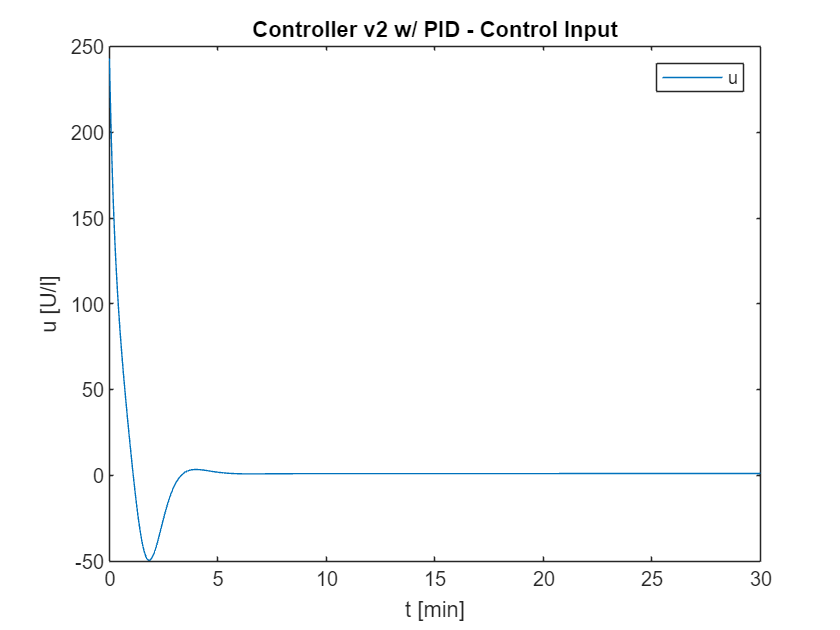

figure;
plot(t, u)
xlim([0,30])
title('Controller v2 w/ PID - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end)), u_max = max(u), u_min = min(u)

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 3.0866
     SettlingTime: 19.5202
      SettlingMin: -49.5667
      SettlingMax: 243.0281
        Overshoot: 2.4149e+04
       Undershoot: 4.9456e+03
             Peak: 243.0281
         PeakTime: 0


u_max = 243.0281

u_min = -49.5667

I risultati in generale non sono molto soddisfacenti: il sistema a ciclo chiuso manifesta picchi positivi e negativi troppo alti per quanto riguarda l'ingresso di controllo. 

Il tuning del controllo è stato realizzato allo scopo di contenere il più possibile questi picchi, cercando di preservare le performance dinamiche desiderate, ad esempio si vuole avere un buon tempo di assestamento, undershoot limitati e l'assenza di oscillazioni. Durante il tuning si sono ottenuti anche controllori con prestazioni dinamiche ma che comportano un eccessivo aumento degli sforzi di controllo, mentre ridurre lo sforzo di controllo si paga in termini di prestazioni dinamiche. Dunque, il controllore presentato rappresenta il migliore trade-off fra questi due aspetti che, tuttavia, non è soddisfacente.

Un ulteriore motivo per cui il controllore PID potrebbe avere performance peggiori è l'esigenza di aggiungere un ulteriore polo per la fisica realizzabilità del controllore. Ciò accade perché il PID non sfrutta la conoscenza di $\dot{\;y_d }$ come accade col controllore precedente.

Per ulteriori simulazioni con riferimenti tempo varianti fare riferimento al seguente file Simulink:

open_system('v2_sim_PID.slx')

### Feedback linearization + PID con un polo

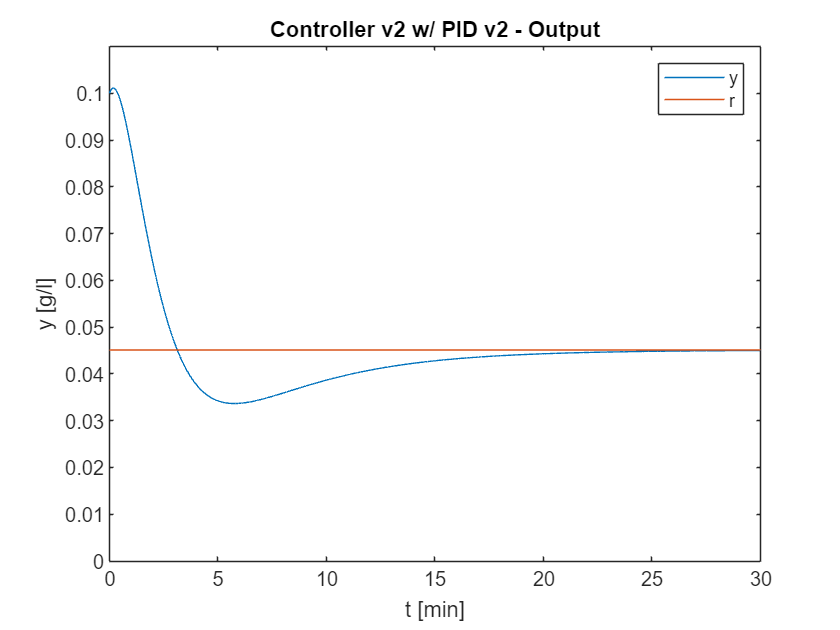

s = tf('s');
C = 1.9133*(s+0.2893)*(s+0.2775)/s;
C = pid(C);
simout = sim('v2_sim_PID_ff.slx');
y = simout.y;
t = simout.t.Time;
u = simout.u;
figure;
plot(t, y)
xlim([0,30])
title('Controller v2 w/ PID v2 - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

y_stepinfo = stepinfo(y,t,y(end)), undershoot=abs(min(y)-0.045102)/0.045102

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 18.3808
     SettlingTime: 19.4023
      SettlingMin: 0.0337
      SettlingMax: 0.1011
        Overshoot: 124.2150
       Undershoot: 0
             Peak: 0.1011
         PeakTime: 0.1798


undershoot = 0.2535

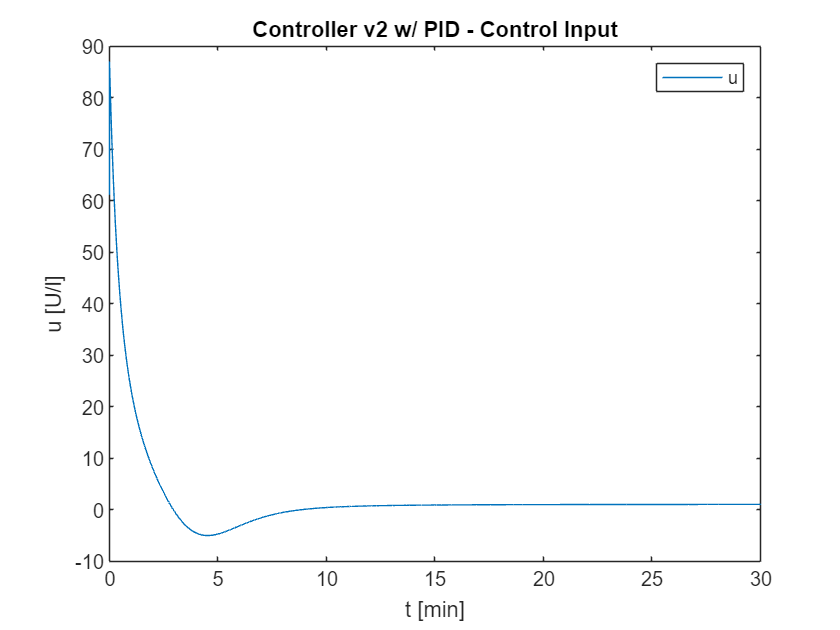

figure;
plot(t, u)
xlim([0,30])
title('Controller v2 w/ PID - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end)), u_max = max(u), u_min = min(u)

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 7.8070
     SettlingTime: 30.0000
      SettlingMin: -5.0508
      SettlingMax: 87.0890
        Overshoot: 8.5895e+03
       Undershoot: 503.9494
             Peak: 87.0890
         PeakTime: 3.1522e-10


u_max = 87.0890

u_min = -5.0508

### Feedback linearization + LQI

Un ultimo tentativo di progettazione è stato fatto con LQI sul sistema "linearizzato" $\frac{1}{s^2 }$.

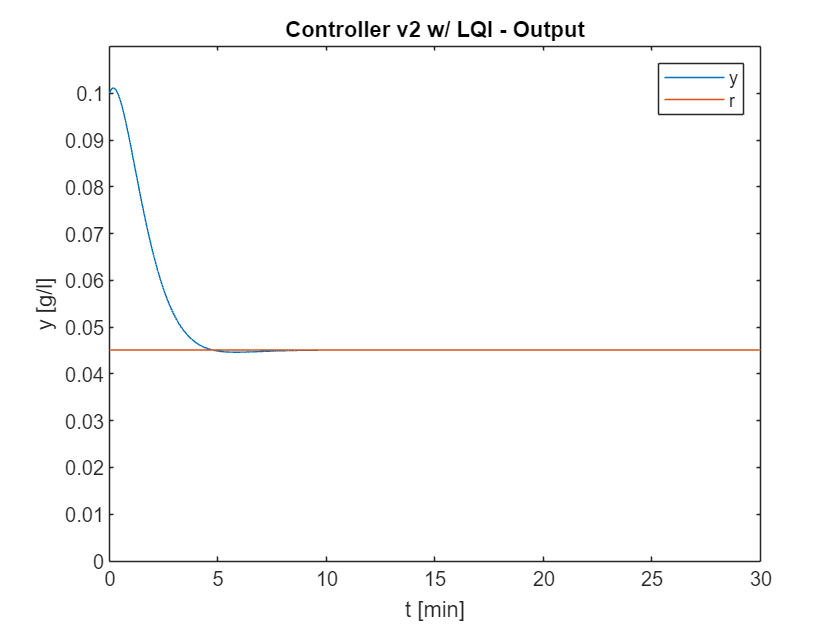

clear all, clc;

A = [0 1; 0 0];
B = [0; 1];
C = [1 0];
D = 0;
sys = ss(A, B, C, D);

Qu = 1;
Qx = [2 0 0;0 2 0;0 0 1];
[K,S,e] = lqi(sys,Qx,Qu,0);

simout = sim('v2_sim_LQI.slx');
y = simout.y;
t = simout.t.Time;
u = simout.u;
figure;
plot(t, y)
xlim([0,30])
title('Controller v2 w/ LQI - Output')
hold on
plot(t,ones(size(t))*0.045102)
ylabel('y [g/l]')
xlabel('t [min]')
legend('y','r')
ylim([0 0.11])

y_stepinfo = stepinfo(y,t,y(end)), undershoot=abs(min(y)-0.045102)/0.045102

y_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 4.1435
     SettlingTime: 4.2290
      SettlingMin: 0.0446
      SettlingMax: 0.1011
        Overshoot: 124.1821
       Undershoot: 0
             Peak: 0.1011
         PeakTime: 0.1776


undershoot = 0.0103

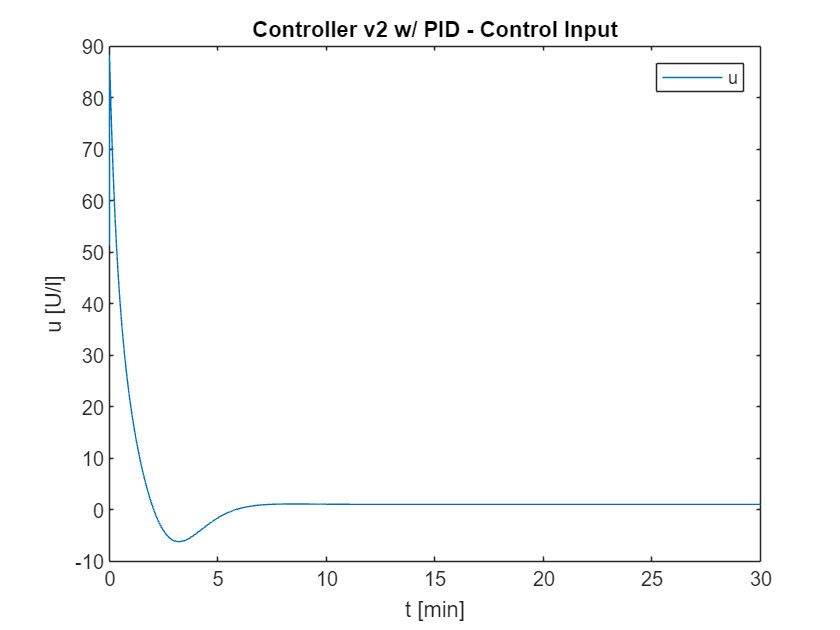

figure;
plot(t, u)
xlim([0,30])
title('Controller v2 w/ PID - Control Input')
ylabel('u [U/l]')
xlabel('t [min]')
legend('u')

u_stepinfo = stepinfo(u,t,u(end)), u_max = max(u), u_min = min(u)

u_stepinfo = struct with fields:
         RiseTime: 0
    TransientTime: 5.3823
     SettlingTime: 10.8616
      SettlingMin: -6.2324
      SettlingMax: 88.3352
        Overshoot: 8.7138e+03
       Undershoot: 621.8504
             Peak: 88.3352
         PeakTime: 3.5755e-10


u_max = 88.3352

u_min = -6.2324

Il file Simulink relativo a tale controllore è il seguente:

open_system('v2_sim_LQI.slx')

Le simulazioni con tale controllore restituiscono degli errori in quanto la variabile $x_1$ si annulla (e l'ingresso linearizzante impone $x_1 \not= 0$). Per verificare la correttezza del controllore allora si è proceduto a simulare il controllore col sistema "ideale" $\frac{1}{s^2 }$.